# Validate Python

## Do_OB13_ISO532_1.m

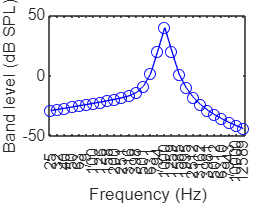


fname = [basepath_SQAT 'sound_files' filesep 'reference_signals' filesep 'RefSignal_Loudness_ISO532_1.wav'];
[insig,fs] = audioread(fname);
dBFS = 94; % A priori knowledge
[OB_filt,fc] = Do_OB13_ISO532_1(insig,fs);
% Sub example: obtaining the calibrated RMS level of each band:
OB_lvls = 20*log10(rms(OB_filt))+dBFS;

figure;
semilogx(fc,OB_lvls,'bo-'); hold on;
set(gca,'XLim',[min(fc)-1 max(fc)+1000]);
set(gca,'XTick',fc);
set(gca,'XTickLabel',round(fc));
xlabel('Frequency (Hz)');
ylabel('Band level (dB SPL)');


% Total level of the input signal:
lvl_orig = 20*log10(rms(insig))+dBFS;
fprintf('Level as obtained directly from the input signal=%.1f dB SPL\n',lvl_orig);

Level as obtained directly from the input signal=40.0 dB SPL



% The sum of the power of each band leads to the total level:
lvl_from_outsig = 10*log10(sum(10.^(OB_lvls/10))); % '/10' means squared, therefore it is 10*log10()
fprintf('Level obtained from the filtered signals=%.1f dB SPL\n',lvl_from_outsig);

Level obtained from the filtered signals=40.1 dB SPL


## Gen_weighting_filters.m

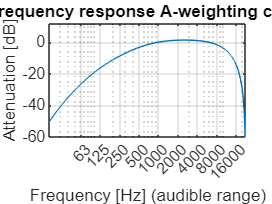

fs = 44100; % Hz
Gen_weighting_filters(fs,'A');

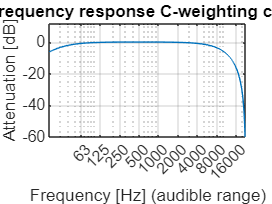


fs = 44100; % Hz
Gen_weighting_filters(fs,'C');

## Do_SLM

%%% Creating a sinuoid with an RMS of 60 dB SPL:
fs = 44100;
freq = 1000; % Hz
dur = 1; % s
t = 0:1/fs:dur-1/fs;
dBFS = 94; % full scale convention
target_lvl = 60; % 60 dB SPL
cal_factor = 10^((target_lvl-dBFS)/20);
A = 1*cal_factor*sqrt(2); % 1=full scale; sqrt(2)=relationship between RMS and peak value for a sinusoid
insig = A*sin(2*pi*freq*t); % zero phase sinusoid centred at f=1000;

%%% Obtaining its A-weighted amplitude, with a fast weighting:
outsig_dB = Do_SLM(insig,fs,'A','f',dBFS); % A-weighting

Do_SLM: Row array detected as an input to this function. The default is a column-wise array.


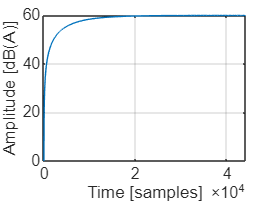

figure;
plot(outsig_dB); grid on;
xlabel('Time [samples]');
ylabel('Amplitude [dB(A)]');

## Get_Leq.m

fs = 48e3;                                     % sampling rate (Hz)

%% Example 1 – overall Leq from a 1-s SPL trace
lvls_1s_dB  = 60 + 3*randn(fs,1);              % 1-s vector, mean 60 dB, SD 3 dB
Leq_total   = Get_Leq(lvls_1s_dB);             % whole-signal mode
fprintf('Example 1 – overall Leq: %.2f dB\n', Leq_total);

Example 1 – overall Leq: 61.03 dB



%% Example 2 – running 1-s Leq every 0.1 s over a 5-s trace
duration_s  = 5;
lvls_5s_dB  = 60 + 3*randn(fs*duration_s,1);   % synthetic 5-s trace
dt_s        = 0.1;                             % hop size  (s)
frame_s     = 1.0;                             % window length (s)
Leq_running = Get_Leq(lvls_5s_dB,fs,dt_s,frame_s);

fprintf('Example 2 – running Leq vector length: %d\n', numel(Leq_running));

Example 2 – running Leq vector length: 41


fprintf('First ten values: %s\n', mat2str(round(Leq_running(1:10),2)));

First ten values: [61.02 61.04 61.04 61.05 61.05 61.05 61.05 61.06 61.06 61.05]
